% Tutorial for Cell Designer Functions

% This script will provide a detailed guide on how to use functions in 
% OVERLAY/src/Strain-Designer as well as the concepts behind algorithms

initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.30.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    0 	    - 	    0 	    - 	    - 	    0
	matlab  

changeCobraSolver('gurobi','all',1);


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021b.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021b.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021b.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to M

clc;

## Prepare PC-model

% In this tutorial, we will use S. cerevisiae metabolic reconstruction 
% iMM904 as an example 

if ~exist('model_ori','var')
%     model_ori = readCbModel('iML1515.xml');
    model_ori = readCbModel('iMM904.xml');
end

% rxnIdx.biomass = 2669;
% rxnIdx.EX_glc = 181;
% rxnIdx.EX_o2 = 1982;
% rxnIdx.EX_succ = 594;

rxnIdx.biomass = 1521;
rxnIdx.EX_glc = 508;
rxnIdx.EX_o2 = 599;
rxnIdx.EX_succ = 594;

% This model is setup to solely grow on glucose

model_ori.lb(rxnIdx.EX_o2) = -1000; % alleviate oxygen constraint

FBAsol = optimizeCbModel(model_ori,'max');
fprintf('With glucose: growth rate: %.3f hr^-1\n',FBAsol.f);

With glucose: growth rate: 0.975 hr^-1


fprintf('              glucose consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(rxnIdx.EX_glc));

              glucose consumption rate: -10.000 mmol/gDW/h


fprintf('              oxygen consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(rxnIdx.EX_o2));

              oxygen consumption rate: -24.262 mmol/gDW/h



% Check if glucose is truly the sole carbon source

model = model_ori;
model.lb(rxnIdx.EX_glc) = 0;

FBAsol = optimizeCbModel(model,'max');
if ~FBAsol.stat
    fprintf('Without glucose: infeasible\n');
else
    fprintf('Without glucose: growth rate: %.3f hr^-1\n',FBAsol.f);
    fprintf('                 glucose consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(rxnIdx.EX_glc));
    fprintf('                 oxygen consumption rate: %.3f mmol/gDW/h\n',FBAsol.v(rxnIdx.EX_o2));
end

Without glucose: infeasible



% This is not an demonstration of OVERLAY, so PC-model formulation will be
% greatly simplified. 
% 
% The 'pcModel' function can also formulate PC-model without specified 
% protein FASTA file, but instead provide an average protein length for 
% protein molecular weight calculation. This will reduce the rigor of the 
% resulted PC-model, but it can be used for testing the workflow and
% investigating the feasibility of study before starting. Here I will
% utilize this feature.

if ~exist('model_pc_ori','var')
    model_pc_ori = pcModel(model_ori,200,150);
end

Input protein length: 200
Constructing k_eff matrix...done
Parsing geneRules and constructing C matrix...done
Adding protein metabolites and protein exchange reactions...done
Adding complex metabolites and cplx formation reactions...done
Adding enzymes metabolites, enzyme formation, and enzyme exchange reactions...done
Adding enzymatic constraints to the model...done
Adding protein weight constraint to the model...done



% Here we specify the average length of proteins in E. coli to be 200 aa
% long, which substitutes for the FASTA filename. The protein weight
% constraint is set at 150mg/gDW or 15% of dry weight. Details about this 
% function are explained in the other tutorial.

% We will not refine the PC-model here because this is only a showcase for
% cell designer functions.

## PC-OptKnock

% PC-OptKnock has identical idea to OptKnock but deals with PC-model. This
% allows more practical gene-knockout suggestions from the solver. 

% Functions in this section can be very time consuming to run and solve, so
% please have one of your better device and take your time. 

% The model struct for OptKnock or PC-OptKnock can be very handily 
% constructed by calling a single function. Let's try doing the regular
% OptKnock first by using M-model and specifying the PCBool 
% (PCBool = false). 

if ~exist('model_ok','var')
    [model_ok,param] = formulatePCOptKnock(model_ori,1,0.05,true,false);
end

Configuring MILP from model...FVA...done
Adding bilevel variables...done
Adding bilevel constraints...dual cons...mu/eta...sigma bounds...strongDuality...binary cons...Max KO (K = 1)...done



% Let's inspect the MILP model's structure:
% 
% Variables (15437 in total):
%   - 2712 metabolic reactions
%   - 1877 w variables, one for each metabolite
%   - 2712 a, b, y, and sigma variables, respectively, one set of these 
%     variables for each metabolic reaction
% 
% Constraints (20863 in total):
%   - 1877 metabolites
%   - 2712 dual constraints, one for each metabolic reaction
%   - 2712 pairs of eta and mu constraints, one pair for each metabolic
%     reactions
%   - 2712 pairs of sigma_L and sigma_U constraints, one pair for each
%     metabolic reactions
%   - 1 strong duality constraint
%   - 2712 pairs of lb_y and ub_y constraints, one pair for each metabolic
%     reactions
%   - 1 maxKO constraint

% Before solving this MILP, we still need to set the objective function

if ~exist('OKsol','var')
    model_ok.obj(rxnIdx.EX_succ) = 1;
    model_ok = changeNumKO(model_ok,1);
    OKsol = gurobi(model_ok,param);
end

Academic license - for non-commercial use only - expires 2024-06-07
Gurobi Optimizer version 9.1.2 build v9.1.2rc0 (mac64)
Thread count: 8 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 12267 rows, 9111 columns and 37075 nonzeros
Model fingerprint: 0x2ada14fa
Variable types: 7534 continuous, 1577 integer (0 binary)
Coefficient statistics:
  Matrix range     [6e-06, 1e+06]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-03, 1e+06]
  RHS range        [1e+00, 2e+03]
Presolve removed 4206 rows and 1535 columns
Presolve time: 0.10s
Presolved: 8061 rows, 7576 columns, 28823 nonzeros
Variable types: 6126 continuous, 1450 integer (1450 binary)

Root relaxation: objective 1.455072e+01, 6763 iterations, 0.53 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   14.55072    0    3          -   14.55072      -     -    1s
H    0     0 


% Now find knocked out reactions and implement it

idx = find(~OKsol.x(find(startsWith(model_ok.varnames,'y_'))));
model_test = model_ori;
model_test.lb(idx) = 0;
model_test.ub(idx) = 0;

FBAsol = optimizeCbModel(model_test,'max');

% =========================================================================
% 
% Now let's try PC-OptKnock
% 
% Construct the MILP struct for PC-OptKnock from PC-model while setting the
% PCBool to true. This will take significantly longer than constructing the
% MILP struct for the regular OptKnock. 

if ~exist('model_pcok','var')
    [model_pcok,param] = formulatePCOptKnock(model_pc_ori,1,0.05,true,true);
end

Configuring MILP from model...FVA...done
Adding bilevel variables...done
Adding bilevel constraints...dual cons...mu/eta...sigma bounds...strongDuality...binary cons...Max KO (K = 1)...done
Fixing non-protein binary variables to 1...Keeping growth-essential proteins open...done



yIdx = find(startsWith(model_pcok.varnames,'y_')); % binary var index
models_sol = {};

% Let's now first try doing only 1 knockout. You ALWAYS want to start with
% K = 1 and work your way up. 

K_init = 1;

model_pcok.obj(rxnIdx.EX_succ) = 1; % specify the outer objective
model_pcok = changeNumKO(model_pcok,K_init); % set K
PCOKsol = gurobi(model_pcok,param);

Academic license - for non-commercial use only - expires 2024-06-07
Gurobi Optimizer version 9.1.2 build v9.1.2rc0 (mac64)
Thread count: 8 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 64805 rows, 47735 columns and 176813 nonzeros
Model fingerprint: 0xd3036362
Variable types: 39201 continuous, 8534 integer (0 binary)
Coefficient statistics:
  Matrix range     [6e-06, 1e+06]
  Objective range  [1e+00, 1e+00]
  Bounds range     [7e-04, 1e+06]
  RHS range        [1e+00, 9e+03]
Presolve removed 53702 rows and 26420 columns
Presolve time: 0.95s
Presolved: 11103 rows, 21315 columns, 55658 nonzeros
Variable types: 20520 continuous, 795 integer (795 binary)

Root relaxation: objective 1.455072e+01, 11083 iterations, 1.23 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   14.55072    0    3          -   14.55072      -     -    3s
H    0

K = 1: EX_succ_e = 0.66, mu = 0.21


Closed proteins: EX_protein_Q0250


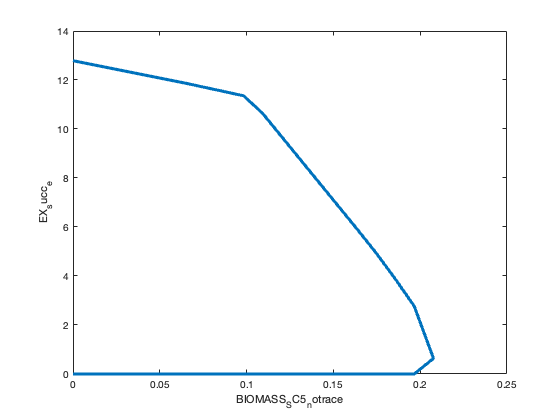


% If we do get a growth-coupling solution (we should according to the
% design), we can get a copy of PC-model and implement the knockout to see
% if it is indeed growth-coupled. 

if PCOKsol.x(rxnIdx.EX_succ) > 1e-6

    idx = find(~PCOKsol.x(yIdx));
    models_sol{1} = model_pc_ori;
    models_sol{1}.lb(idx) = 0;
    models_sol{1}.ub(idx) = 0;
    
    FBAsol = optimizeCbModel(models_sol{1},'max');
    fprintf('K = %d: EX_succ_e = %.2f, mu = %.2f\n',K_init,FBAsol.v(rxnIdx.EX_succ),FBAsol.v(rxnIdx.biomass));
    fprintf('Closed proteins: %s\n',model_pc_ori.rxns{idx(1)});
    drawSolutionEnvelope(models_sol{1},model_pc_ori.rxns{rxnIdx.biomass},model_pc_ori.rxns{rxnIdx.EX_succ},20,true);
else
    error('No growth coupling solution found by PC-OptKnock. Please consider increase K');
end


% In this case, we find a growth-coupling solution with only K = 1, which 
% is an ideal scenario. If PCOKsol.x(rxnIdx.EX_succ) is almost 0, you should
% increase K by 1 and re-run this section. 
% 
% Since we have found a solution, it is attempting to increase the
% productivity. The most computationally efficient way is to set K = 2 and
% fixing the previous growth-coupling solution. We call this trial K = 1+1.
% This finds a local optima starting from the existing solution of K = 1, 
% which is very likely less optimized than computing the true K = 2 but 
% much more efficient. 
% 
% So let's do K = 1+1 here

model_pcok_alt = changeNumKO(model_pcok,K_init+1);
model_pcok_alt.ub(yIdx(idx)) = 0; % forcing the previous knockout
PCOKsol = gurobi(model_pcok_alt,param);

Academic license - for non-commercial use only - expires 2024-06-07
Gurobi Optimizer version 9.1.2 build v9.1.2rc0 (mac64)
Thread count: 8 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 64805 rows, 47735 columns and 176813 nonzeros
Model fingerprint: 0xbe12f9fd
Variable types: 39201 continuous, 8534 integer (0 binary)
Coefficient statistics:
  Matrix range     [6e-06, 1e+06]
  Objective range  [1e+00, 1e+00]
  Bounds range     [7e-04, 1e+06]
  RHS range        [1e+00, 9e+03]
Presolve removed 53752 rows and 26488 columns
Presolve time: 0.94s
Presolved: 11053 rows, 21247 columns, 55430 nonzeros
Variable types: 20453 continuous, 794 integer (794 binary)
Root relaxation: objective 1.207991e+01, 11514 iterations, 1.27 seconds
    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   12.07991    0    1          -   12.07991      -     -    2s
H    0  


idx = find(~PCOKsol.x(find(startsWith(model_pcok_alt.varnames,'y_'))));
models_sol{2} = model_pc_ori;
models_sol{2}.lb(idx) = 0;
models_sol{2}.ub(idx) = 0;

FBAsol = optimizeCbModel(models_sol{2},'max');
fprintf('K = %d+1: EX_succ_e = %.2f, mu = %.2f\n',K_init,FBAsol.v(rxnIdx.EX_succ),FBAsol.v(rxnIdx.biomass));

K = 1+1: EX_succ_e = 7.38, mu = 0.13


fprintf('Closed proteins: %s, %s\n',model_pc_ori.rxns{idx(1)},model_pc_ori.rxns{idx(2)});

Closed proteins: EX_protein_Q0250, EX_protein_YBR196C


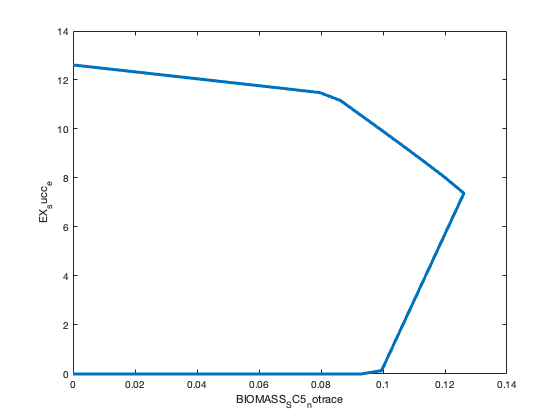

drawSolutionEnvelope(models_sol{2},model_pc_ori.rxns{rxnIdx.biomass},model_pc_ori.rxns{rxnIdx.EX_succ},20,true);


% And then K = 1+1+1: 

model_pcok_alt = changeNumKO(model_pcok,K_init+2);
model_pcok_alt.ub(yIdx(idx)) = 0;
PCOKsol = gurobi(model_pcok_alt,param);

Academic license - for non-commercial use only - expires 2024-06-07
Gurobi Optimizer version 9.1.2 build v9.1.2rc0 (mac64)
Thread count: 8 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 64805 rows, 47735 columns and 176813 nonzeros
Model fingerprint: 0x2ec99709
Variable types: 39201 continuous, 8534 integer (0 binary)
Coefficient statistics:
  Matrix range     [6e-06, 1e+06]
  Objective range  [1e+00, 1e+00]
  Bounds range     [7e-04, 1e+06]
  RHS range        [1e+00, 9e+03]
Presolve removed 53766 rows and 26511 columns
Presolve time: 1.10s
Presolved: 11039 rows, 21224 columns, 55373 nonzeros
Variable types: 20431 continuous, 793 integer (793 binary)
Root relaxation: objective 1.190875e+01, 10286 iterations, 1.00 seconds
    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   11.90875    0    3          -   11.90875      -     -    2s
H    0  


idx = find(~PCOKsol.x(find(startsWith(model_pcok_alt.varnames,'y_'))));
models_sol{3} = model_pc_ori;
models_sol{3}.lb(idx) = 0;
models_sol{3}.ub(idx) = 0;

FBAsol = optimizeCbModel(models_sol{3},'max');
fprintf('K = %d+1+1: EX_succ_e = %.2f, mu = %.2f\n',K_init,FBAsol.v(rxnIdx.EX_succ),FBAsol.v(rxnIdx.biomass));

K = 1+1+1: EX_succ_e = 7.86, mu = 0.12


fprintf('Closed proteins: %s, %s, %s\n',model_pc_ori.rxns{idx(1)},model_pc_ori.rxns{idx(2)},model_pc_ori.rxns{idx(3)});

Closed proteins: EX_protein_Q0250, EX_protein_YBR196C, EX_protein_YKL029C


drawSolutionEnvelope(models_sol{3},model_pc_ori.rxns{rxnIdx.biomass},model_pc_ori.rxns{rxnIdx.EX_succ},20,true);


% As you can see, we could keep stacking up with minor computational effort
% and achieve much better growth-coupling strain. 
% If we try to solve K = 3 from the beginning, it will cost more than 100x
% resources, although it can guarantee to reach a global optima, of which
% in this case we don't neccesarily need to achieve anyway.

## MOPA

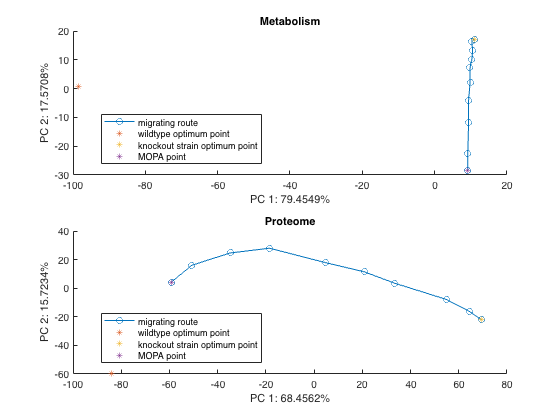

% The algorithm of MOPA (minimization of proteome adjustment) is adapted 
% from MOMA (minimization of metabolic adjustment). This suggests that once
% a genomic modification is made, the proteome (metabolism) will gradually
% shift from the old operating point toward the new. As a consequence, the
% short-term behavior of the modified strain may appear to be sub-optimal,
% because the cell is still operating around the old operating point. 
% 
% Let's use the PC-OptKnock K = 1+1+1 result as an example, note that these
% are the knockouts from that tutorial section:

KOProteins = {'EX_protein_Q0250','EX_protein_YBR196C','EX_protein_YKL029C'};

proteinExIdx = find(startsWith(model_pc_ori.rxns,'EX_protein_'));
metRxnIdx = 1:1577;

% MOPA gives the MOPA solution, wildtype optimum, and KO strain optimum

[MOPAsol,FBAsol_wt,FBAsol_mut] = MOPA(model_pc_ori,KOProteins);

% It is difficult to understand what's going on simply by looking at this
% solution vectors. Here we can use a tweening algorithm, which gives the
% optimal route for the cell to progressively move its proteome toward the
% new operating point. Note in the proteinTween algorithm, the protein is
% re-allocated uniformly between each step, but the metabolism change 
% usually appear non-uniformal. 

FBAsols = proteinTween(models_sol{3},MOPAsol,'BIOMASS_SC5_notrace',10);

% The solution is too high in dimension to visualize, but we can plot the 
% manifold after PCA. Note that PCA need to be done for metabolism and
% proteome separately.

[coef_m,sc_m,~,~,exp_m] = pca([FBAsol_wt.v(metRxnIdx),FBAsols(metRxnIdx,:)]');
[coef_p,sc_p,~,~,exp_p] = pca([FBAsol_wt.v(proteinExIdx),FBAsols(proteinExIdx,:)]');

% Plot the manifold

figure;

subplot(2,1,1);
hold on;
plot(sc_m(2:end,1),sc_m(2:end,2),'o-');
plot(sc_m(1,1),sc_m(1,2),'*');
plot(sc_m(end,1),sc_m(end,2),'*');
plot(sc_m(2,1),sc_m(2,2),'*');
legend({'migrating route','wildtype optimum point','knockout strain optimum point','MOPA point'},'Location','best');
title('Metabolism');
xlabel(['PC 1: ',num2str(exp_m(1)),'%']);
ylabel(['PC 2: ',num2str(exp_m(2)),'%']);

subplot(2,1,2);
hold on;
plot(sc_p(2:end,1),sc_p(2:end,2),'o-');
plot(sc_p(1,1),sc_p(1,2),'*');
plot(sc_p(end,1),sc_p(end,2),'*');
plot(sc_p(2,1),sc_p(2,2),'*');
legend({'migrating route','wildtype optimum point','knockout strain optimum point','MOPA point'},'Location','best');
title('Proteome');
xlabel(['PC 1: ',num2str(exp_p(1)),'%']);
ylabel(['PC 2: ',num2str(exp_p(2)),'%']);


% From this plot, you can indeed see the MOPA solution is the closest to
% the wildtype point, but only for the proteome. The pattern is a lot
% harder to see for metabolic vectors. However, the re-allocation of
% proteome, despite not moving linearly itself, allows an almost linear 
% movement for the metabolism toward the new optimum. This is what we want
% to achieve by MOMA.

## minimalGenome

% The minimal genome is an interesting concept in synthetic biology: by
% reducing the size of the genome while preserving the desired synthetic
% pathway, we can largely avoid regulatory complications and achieve and
% maintain a relatively high productivity. 
% 
% The in-silico minimal genome simulation can be easily done as a MILP
% problem from a PC-model. We are aiming to shutdown as many proteins while
% keeping the growth rate above a threshold, which is conceptually simple.
% However, the MILP can become very expensive to solve as we trying to
% knockout too many proteins at once. Thus, we can also take the step-wise
% approach, although this does not gaurantee to find the global
% optimality, just like the step-wise PC-OptKnock didn't. 
% 
% Let's use the wildtype S. cerevisiae as an example. We want to reduce its
% genome size while preserving the ability to produce succinate and grow to
% a certain degree. 

% TODO